# Lab 5

load("var_6.mat")
h = figure;
set(h, 'DefaultAxesFontSize', 12, 'DefaultAxesFontName', 'Times New Roman');

Logarithm-amplitude frequency response

ax(1) = subplot(2,1,1);
    hold on
    grid on
    plot(w,Lw)
    set(ax(1),'XScale','Log')
    xlabel('\omega,\it rad\rm/\its')
    ylabel('\itL\rm,\it dB')

Phase frequency response

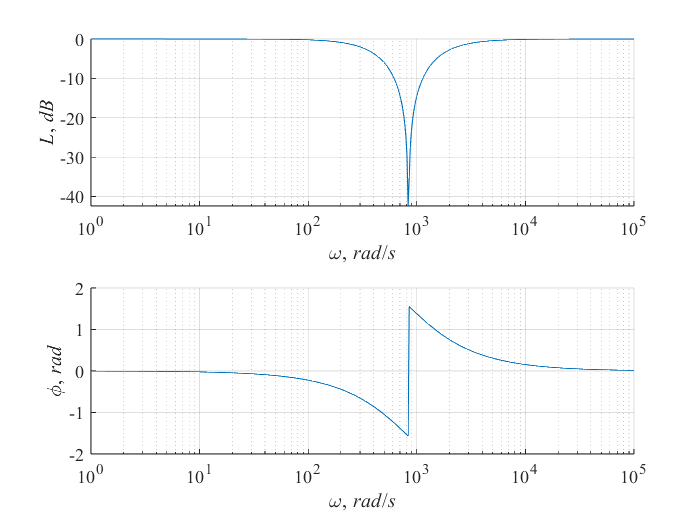

ax(2) = subplot(2,1,2);

    hold on
    grid on
    plot(w,phi)
    set(ax(2),'XScale','Log')
    xlabel('\omega,\it rad\rm/\its')
    ylabel('\phi\rm,\it rad')  

 linkaxes(ax,'x') 

 syms ur ul uc
 syms ir il ic
 syms R L C

 syms dil duc
 syms e
 eq(1) = ur == R*ir;
 eq(2) = ul == L*dil;
 eq(3) = ic == C*duc;
 eq(4) = ur + uc ==e;
 eq(5) = ul - uc ==0;
 eq(6) = ir - il - ic == 0;
 x=[il uc]';
 u=[e]';
 y=[ur]';
 S1 = solve(eq, [dil duc ur ul ir ic]);

$di_l$=

 disp(collect(S1.dil, [il uc e]))

$$\frac{\mathrm{uc}}{L}$$

$\frac{du_c }{\textrm{dt}}$=

 disp(collect(S1.duc,[il uc e]))

$$\left(-\frac{1}{C}\right)\,\mathrm{il}+\left(-\frac{1}{C\,R}\right)\,\mathrm{uc}+\frac{1}{C\,R}\,e$$

$u_r$=

 disp(collect(S1.ur,[il uc e]))

$$-\mathrm{uc}+e$$

 mod.A = [0 1/L;...
          -1/C -1/(C*R)];
 mod.B = [0;...
         1/(C*R)];
 mod.C = [0 -1];
 mod.D = [1];

A=

 disp(mod.A)

$$\left(\begin{array}{cc} 0 & \frac{1}{L}\\ -\frac{1}{C} & -\frac{1}{C\,R} \end{array}\right)$$

B=

 disp(mod.B)

$$\left(\begin{array}{c} 0\\ \frac{1}{C\,R} \end{array}\right)$$

C=

 disp(mod.C)

     0    -1



D=

 disp(mod.D)

     1



**checking**

$\left\lbrack \begin{array}{l}
d\frac{i_l }{\textrm{dt}}\\
d\frac{u_c }{\textrm{dt}}
\end{array}\right\rbrack$=

 disp(collect(mod.A*x+mod.B*u, [il uc e]))

$$\left(\begin{array}{c} \frac{\bar{\mathrm{uc}}}{L}\\ \frac{\bar{e}}{C\,R}-\frac{\bar{\mathrm{il}}}{C}-\frac{\bar{\mathrm{uc}}}{C\,R} \end{array}\right)$$


$$u_r =$$


  disp(collect(mod.C*x+mod.D*u, [il uc e]))

$$\bar{e}-\bar{\mathrm{uc}}$$

## 3.Transfer function

syms s
Wob = mod.C*(s*eye(2)-mod.A)^-1*mod.B+mod.D;


$$\frac{u_r \left(s\right)}{e\left(s\right)}=$$


disp(collect(Wob,s))

$$\frac{\left(C\,L\,R\right)\,s^{2}+R}{\left(C\,L\,R\right)\,s^{2}+L\,s+R}$$

### 4.Estimating

Logarithm-amplitude frequency response

ax(1) = subplot(2,1,1);
    hold on
    grid on
    plot(w,Lw)
    set(ax(1),'XScale','Log')
    xlabel('\omega,\it rad\rm/\its')
    ylabel('\itL\rm,\it dB')

Phase frequency response

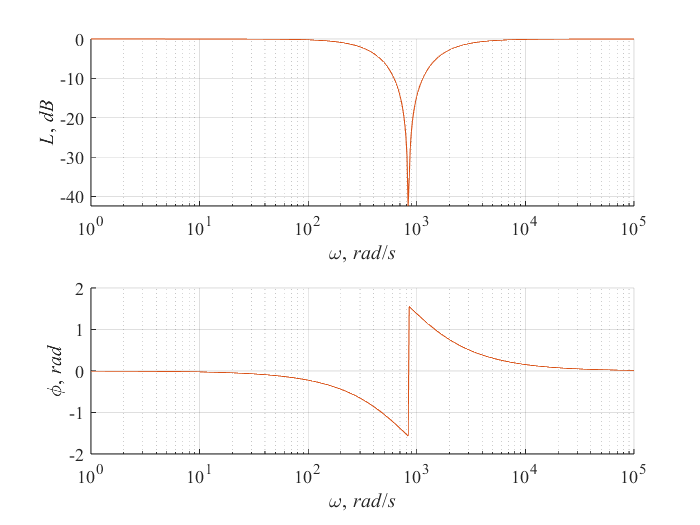

ax(2) = subplot(2,1,2);

    hold on
    grid on
    plot(w,phi)
    set(ax(2),'XScale','Log')
    xlabel('\omega,\it rad\rm/\its')
    ylabel('\phi\rm,\it rad')  

 linkaxes(ax,'x') 

 est.om1 = 831;
 est.T = est.om1^-1;
 fprintf('w = %.1f rad/s\n',est.om1);

w = 831.0 rad/s


 fprintf('T = %.1f ms\n',est.T*1000);

T = 1.2 ms


### find parameter ksi


$$W\left(j\omega \right)=\frac{T^2 {\left(j\omega \right)}^2 +1}{T^2 {\left(j\omega \right)}^2 +2T\xi \left(j\omega \right)+1}$$



$$H\left(j\omega \right)=\left|\frac{T^2 {\left(j\omega \right)}^2 +1}{T^2 {\left(j\omega \right)}^2 +2T\xi \left(j\omega \right)+1}\right|$$



$$H^2 \left(j\omega \right)={\left|\frac{T^2 {\left(j\omega \right)}^2 +1}{T^2 {\left(j\omega \right)}^2 +2T\xi \left(j\omega \right)+1}\right|}^2$$


 syms T ksi om H2
 Wjw = (T^2*(1i*om)^2+1)/(T^2*(1i*om)^2+2^T*ksi*(1i*om)+1);
 eqn = H2 == (-T^2*(om)^2+1)^2/((2*T*ksi*(om))^2+(-T^2*(om)^2+1)^2);
 S2 = solve(eqn,ksi);

$\xi$=

 disp(S2)

$$\left(\begin{array}{c} -\frac{\left(T\,\mathrm{om}-1\right)\,\left(T\,\mathrm{om}+1\right)\,\sqrt{-\frac{H_{2}-1}{H_{2}}}}{2\,T\,\mathrm{om}}\\ \frac{\left(T\,\mathrm{om}-1\right)\,\left(T\,\mathrm{om}+1\right)\,\sqrt{-\frac{H_{2}-1}{H_{2}}}}{2\,T\,\mathrm{om}} \end{array}\right)$$

 ind = 300;
 mes.w = w(ind);
 mes.Lw = Lw(ind);
 mes.H = 10^(mes.Lw/20);
 mes.H2 = mes.H^2;
 est.ksi=(est.T*mes.w-1)*(est.T*mes.w+1)*...
     sqrt(-(mes.H2-1)/mes.H2)/(2*est.T*mes.w)

est = 包含以下字段的 struct :
    om1: 831
      T: 0.0012
    ksi: 0.9778
      s: [0.0000 + 1.0000i 0.0000 + 1.0233i 0.0000 + 1.0471i 0.0000 + 1.0715i 0.0000 + 1.0965i 0.0000 + 1.1220i 0.0000 + 1.1482i 0.0000 + 1.1749i 0.0000 + 1.2023i 0.0000 + 1.2303i 0.0000 + 1.2589i 0.0000 + 1.2882i 0.0000 + 1.3183i 0.0000 + 1.3490i … ]


$\xi$=

disp(est.ksi)

    0.9778



### Estimated frequency response

est.s = 1i*w;
Wf = (est.T^2*est.s.^2+1)./(est.T^2*est.s.^2+2*est.T*est.ksi*est.s+1);
Lf = 20*log10(abs(Wf));
psif = angle(Wf);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

Logarithm-amplitude frequency response

ax(1) = subplot(2,1,1);
    hold on
    grid on
    plot(w,Lw)
    plot(w,Lf) %add this line
    set(ax(1),'XScale','Log')
    xlabel('\omega,\it rad\rm/\its')
    ylabel('\itL\rm,\it dB')

Phase frequency response

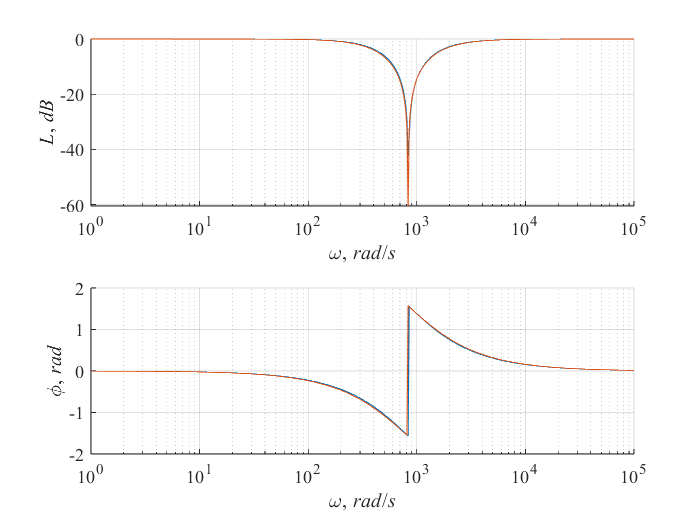

ax(2) = subplot(2,1,2);
    hold on
    grid on
    plot(w,phi)
    plot(w,psif) %add this line
    set(ax(2),'XScale','Log')
    xlabel('\omega,\it rad\rm/\its')
    ylabel('\phi\rm,\it rad')  

 linkaxes(ax,'x')

## Checking

ob.C = 1e-3;
ob.L = est.T^2/ob.C;
ob.R = ob.L/(2*est.T*est.ksi);

Tmdl = 0.05;
Ts = 1e-4;

warning off
Simout = sim('model.slx', 'ReturnWorkspaceOutputs', 'on');
t1 = Simout.torque.time(:) %换代码

t1 =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0003
    0.0007
    0.0013
    0.0019


torq1 = Simout.torque.signals(1).values(1,:)'

torq1 =     1.0000
    0.9998
    0.9988
    0.9938
    0.9691
    0.8549
    0.5805
    0.3443
    0.2706
    0.3612


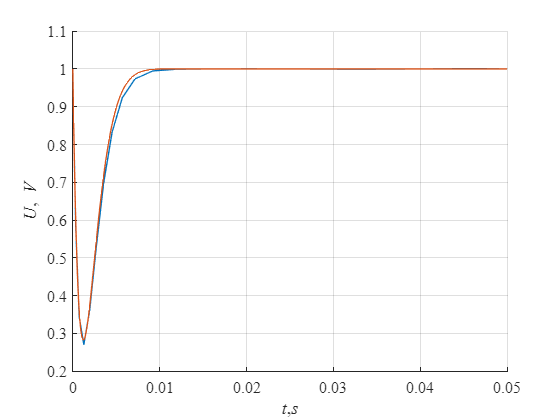

%w1 = Simout.w.signals(1).values(1,:)'



%t1 = Simout.torque(:,1) 
%torq1 = Simout.torque(:,2)
%w1 = Simout.w(:,2)
load('var_6.mat')
warning on

tn = Simout.torque.time(:);
im_y = Simout.torque.signals(1).values(1,:);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
    hold on
    grid on
    plot(tn,im_y)
    plot(t,y)

    xlabel('\itt\rm,\its')
    ylabel('\itU\rm,\it V')
    xlim([0 0.05])

    er = std(im_y-y)

er =     0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422    0.1422
